# **KINOVA Gen3 Manipulator Path Planning using STOMP**

This example shows how to plan a collision-free robot path from an initial to a desired end-effector pose using STOMP ([Stochastic trajectory optimization for motion planning](https://ieeexplore.ieee.org/document/5980280))[1].

## Robot Description and Poses

Load the KINOVA Gen3 rigid body tree (RBT) model.

clear all;
robot_name = 'kinovaGen3';
robot = loadrobot(robot_name, 'DataFormat', 'column'); % Note there are different data formats for loading the robot (chosen in the 2nd argument)

Get the number of joints.

numJoints = numel(homeConfiguration(robot));

Specify the robot frame where the end-effector is attached.

endEffector = "EndEffector_Link"; 

Specify initial and desired end-effector poses. Use inverse kinematics (maps from pose to joint angles) to solve for the initial robot configuration given a desired pose.

% Initial end-effector pose
taskInit = trvec2tform([[0.4 0 0.2]])*axang2tform([0 1 0 pi]);

% Compute current robot joint configuration using inverse kinematics
ik = inverseKinematics('RigidBodyTree', robot);
ik.SolverParameters.AllowRandomRestart = false;
weights = [1 1 1 1 1 1];

currentRobotJConfig = ik(endEffector, taskInit, weights, robot.homeConfiguration);

% The IK solver respects joint limits, but for those joints with infinite
% range, they must be wrapped to a finite range on the interval [-pi, pi].
% Since the the other joints are already bounded within this range, it is
% sufficient to simply call wrapToPi on the entire robot configuration
% rather than only on the joints with infinite range.
currentRobotJConfig = wrapToPi(currentRobotJConfig);

% Final (desired) end-effector pose
taskFinal = trvec2tform([0.15 0.35 0.15])*axang2tform([0 1 0 pi]);  
anglesFinal = rotm2eul(taskFinal(1:3,1:3),'XYZ');
poseFinal = [taskFinal(1:3,4);anglesFinal']; % 6x1 vector for final pose: [x, y, z, phi, theta, psi]

% Final configuration
finalRobotJConfig = ik(endEffector, taskFinal, weights, currentRobotJConfig);
finalRobotJConfig = wrapToPi(finalRobotJConfig);

## Collision Meshes and Obstacles

MATLAB has its own collision world functions to check for and avoid collisions (e.g., collisionSphere, collisionBox, etc). Here, we follow the STOMP paper to set up the voxel world and using the signed Euclidean distance function for this purpose, which is a common practice in robotics perception, mapping, and collision avoidance. We shall still use the MATLAB built-in collision object functions to visualize the object for the convenience. See more details in the following helper functions.

helperCreateObstaclesKINOVA;

Visualize the robot at the initial configuration. You should see the obstacles in the environment as well.

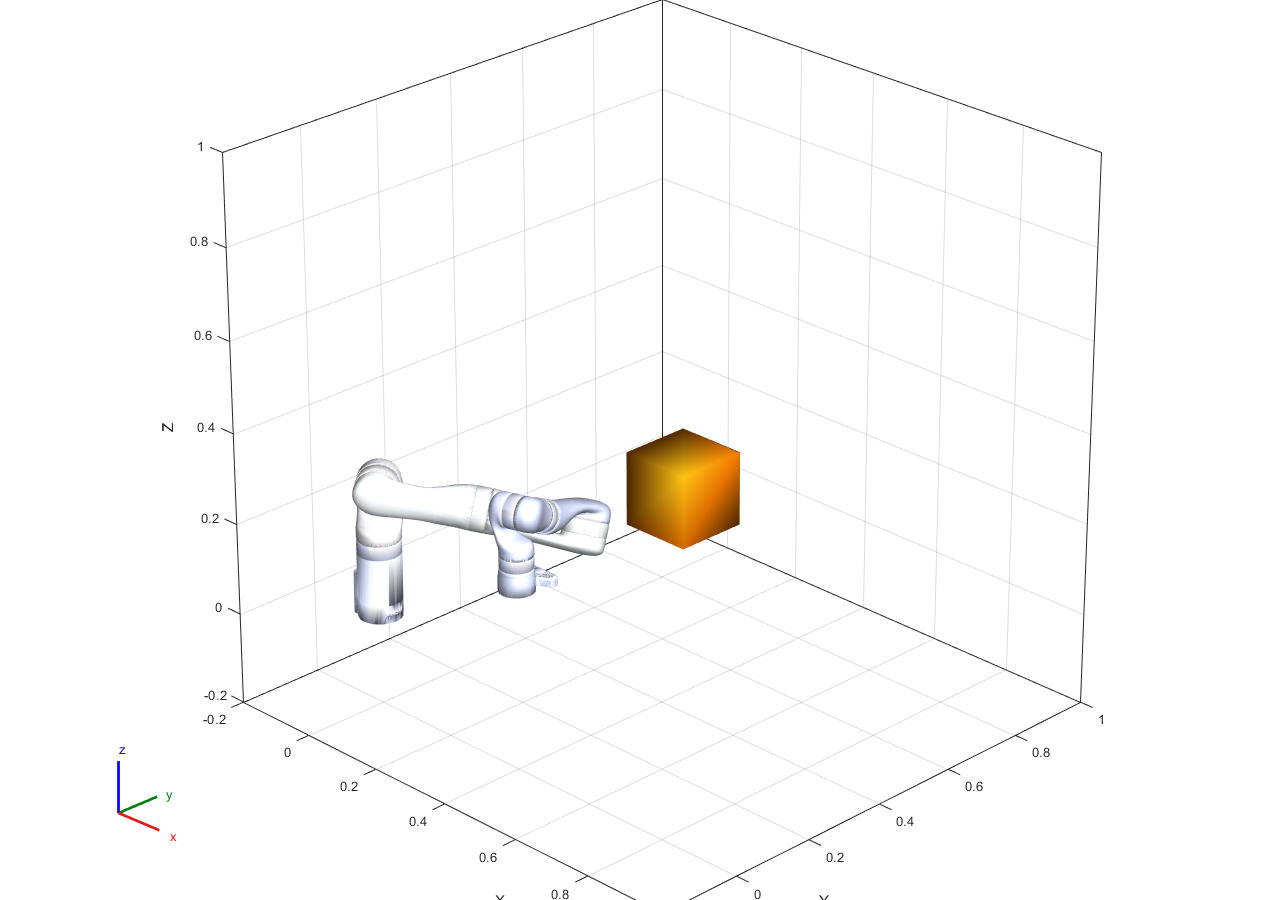

x0 = [currentRobotJConfig', zeros(1,numJoints)];
helperInitialVisualizerKINOVA;
% ==== 放大并规范 3D 视图 ====
fig = gcf; set(fig,'Color','w','Position',[100 100 1280 900]);  % 放大窗口
ax  = gca; view(ax, 45, 25); grid(ax,'on'); box(ax,'on'); hold(ax,'on');
axis(ax,'vis3d'); daspect(ax,[1 1 1]); pbaspect(ax,[1 1 1]);   % 立方比例


xlim(ax,[-0.2, 1]);
ylim(ax,[-0.2, 1]);
zlim(ax,[-0.2, 1]);

camlight(ax,'headlight'); lighting(ax,'gouraud');  % 柔和光照

drawnow;




Specify a safety distance away from the obstacles. This value is used in the inequality constraint function of the nonlinear MPC controller.

safetyDistance = 0.1; 

## Path Planning using STOMP

The following helper function contain the setup and execution of the STOMP algorithm for collision-avoidance planning.

>>> helperSTOMP: INIT — building initial theta from q0 to qT
>>> helperSTOMP: PRECOMPUTE — building A, R, Rinv, M
>>> helperSTOMP: COST0 — evaluating initial Qtheta
>>> helperSTOMP: ENTER LOOP — starting STOMP optimization (no per-iter prints by request)


Q_total = 972.6546

Q_state = 905.8078

RAR = 66.8468

Q_total = 955.5694

Q_state = 888.4399

RAR = 67.1295

Q_total = 931.0414

Q_state = 864.1659

RAR = 66.8755

Q_total = 909.8894

Q_state = 843.2453

RAR = 66.6441

Q_total = 906.6777

Q_state = 839.9894

RAR = 66.6883

Q_total = 884.5842

Q_state = 818.0106

RAR = 66.5735

Q_total = 869.6991

Q_state = 801.8472

RAR = 67.8519

Q_total = 857.2038

Q_state = 789.0257

RAR = 68.1781

Q_total = 838.6101

Q_state = 770.3485

RAR = 68.2616

Q_total = 831.2806

Q_state = 763.3460

RAR = 67.9346

Q_total = 812.5531

Q_state = 745.1125

RAR = 67.4406

Q_total = 793.8742

Q_state = 726.8832

RAR = 66.9910

Q_total = 787.5301

Q_state = 720.8366

RAR = 66.6935

Q_total = 783.5248

Q_state = 716.8614

RAR = 66.6634

Q_total = 768.7395

Q_state = 702.6745

RAR = 66.0650

Q_total = 767.9427

Q_state = 701.7559

RAR = 66.1868

Q_total = 764.7515

Q_state = 698.8057

RAR = 65.9458

Q_total = 755.7237

Q_state = 690.3505

RAR = 65.3732

Q_total = 754.5870

Q_state = 689.0498

RAR = 65.5372

Q_total = 753.0709

Q_state = 687.9598

RAR = 65.1111

Q_total = 750.9292

Q_state = 685.3166

RAR = 65.6126

Q_total = 747.2561

Q_state = 681.7689

RAR = 65.4873

Q_total = 743.5234

Q_state = 678.7667

RAR = 64.7567

Q_total = 741.9166

Q_state = 676.5963

RAR = 65.3203

Q_total = 740.2281

Q_state = 675.1384

RAR = 65.0896

Q_total = 737.2926

Q_state = 673.3804

RAR = 63.9122

Q_total = 734.1289

Q_state = 670.5808

RAR = 63.5481

Q_total = 732.7298

Q_state = 669.7106

RAR = 63.0192

Q_total = 731.5648

Q_state = 668.6352

RAR = 62.9296

Q_total = 729.6754

Q_state = 667.5850

RAR = 62.0904

Q_total = 728.5126

Q_state = 666.8100

RAR = 61.7026

Q_total = 728.0208

Q_state = 665.8105

RAR = 62.2103

Q_total = 728.1412

Q_state = 665.3605

RAR = 62.7807

Q_total = 727.6767

Q_state = 664.9355

RAR = 62.7412

Q_total = 726.5165

Q_state = 663.8855

RAR = 62.6310

Q_total = 724.9753

Q_state = 662.9359

RAR = 62.0393

Q_total = 723.7668

Q_state = 661.5990

RAR = 62.1678

Q_total = 722.3133

Q_state = 660.8174

RAR = 61.4959

Q_total = 721.2948

Q_state = 659.9548

RAR = 61.3400

Q_total = 719.8119

Q_state = 659.1624

RAR = 60.6495

Q_total = 718.5190

Q_state = 658.4844

RAR = 60.0347

Q_total = 717.8275

Q_state = 657.9132

RAR = 59.9143

Q_total = 716.6305

Q_state = 657.1084

RAR = 59.5222

Q_total = 716.1093

Q_state = 656.7045

RAR = 59.4048

Q_total = 715.9191

Q_state = 656.5601

RAR = 59.3591

Q_total = 715.2861

Q_state = 656.2614

RAR = 59.0247

Q_total = 714.4372

Q_state = 655.6109

RAR = 58.8263

Q_total = 714.6783

Q_state = 655.2238

RAR = 59.4545

Q_total = 714.1694

Q_state = 654.8010

RAR = 59.3684

Q_total = 713.7453

Q_state = 654.4543

RAR = 59.2910

Q_total = 713.7943

Q_state = 654.1371

RAR = 59.6573

Maximum iteration (50) has reached.
>>> helperSTOMP: LOOP FINISHED
STOMP Finished.
>>> helperSTOMP: COLLISION CHECK — running checkCollision over the planned trajectory


isTrajectoryInCollision = logical
   0


>>> helperSTOMP: COLLISION CHECK DONE — any collision? false
>>> helperSTOMP: TRAINING VIDEO — begin
>>> helperSTOMP: TRAINING VIDEO — saved KinvaGen3_Training.avi
>>> helperSTOMP: TRAJ VIDEO — begin
>>> helperSTOMP: TRAJ VIDEO — saved KinvaGen3_wEEConY3.avi
>>> helperSTOMP: DISPLAY — showing planned trajectory


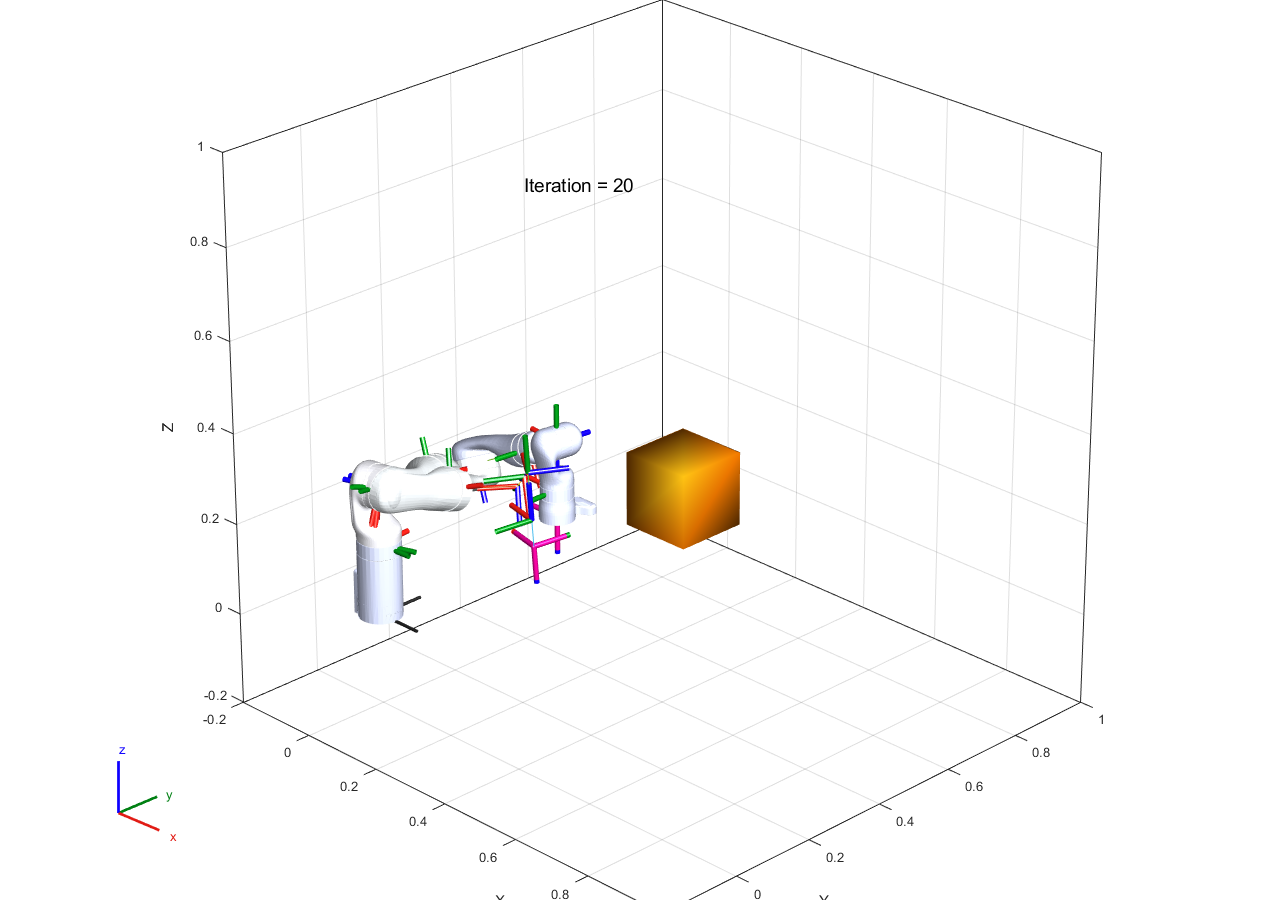

>>> helperSTOMP: DISPLAY — done
>>> helperSTOMP: SAVE — writing theta to MAT file
>>> helperSTOMP: SAVE — saved Theta_nDisc20_nPaths_30.mat


helperSTOMP;

[1] M. Kalakrishnan, S. Chitta, E. Theodorou, P. Pastor and S. Schaal, "STOMP: Stochastic trajectory optimization for motion planning," *2011 IEEE International Conference on Robotics and Automation*, 2011, pp. 4569-4574, doi: 10.1109/ICRA.2011.5980280.